# MOOS ".klog" Time and Location Processor

## Objective (Read before Run All)

For the sake of processing sonar data using the SonarTRX software, the Riptide AUV's recorded position needs to be inputed as alternate data. Where the MOOS logs included information such as GPS time and NAV latitude, longitide, altitude, and heading; This data needs to be processed individually before recombining in a single (presumably) useable file processable by the SonarTRX software. 

The end goal for this script is to simply prompt the user to select the the desired MOOSLog folder before processing the selected data and finally outputting a useable file into a folder of the user's choice.

## What this script does (Read before Run All)

This livescript is meant to easily process .klog files produced after the splitting process that occurs when using the MOOS alogviewer. The .klog files are kept in a single folder per mission with the name convention MOOSLog_DD_MM_YYYY_____HH_MM_SS_altvtmp. The primary files of interest are the GPS logs which contain date and time of the mission and the NAV logs which recorded assumed latitude, longitude, altitude, and heading information necessary to map the sonar data. 

Note: Currently altitude isn't recorded by default when operating on depth based missions as we have (up until Winter 2020 at least). The alternative could be to somehow use the NAV depth data to extract useable information.

## Desired variables (Modify then Run All)

Suggested variables: GPS_YEAR, _MONTH, _DAY, _HOUR, _MINUTE, _SECOND; NAV_LATITUDE, _LONGITUDE, _HEADING, _DEPTH, _ALTITIUDE

Optional variables: NAV_SPEED, _X, and _Y; DESIRED_DEPTH, _HEADING, and _SPEED

Enter your target variables into the cell array below exacly how it is spelled in the MOOSLog folder, sans the ".klog"

target = {'GPS_YEAR' 'GPS_MONTH' 'GPS_DAY' 'GPS_HOUR' 'GPS_MINUTE' 'GPS_SECOND'...
      'NAV_LAT' 'NAV_LONG' 'NAV_HEADING'};% 'NAV_DEPTH' 'NAV_ALTITIDE'};

Note: This section is temporary until I am sure of what variables are actually required.

## NAV derivations (additional information)

Quick note: NAV increments roughly 10 times a second where GPS increments every 1 or 2 seconds. GPS data seems to line up fine and is never off by more than 0.00001 (or roughly a meter). 

X = GPS @ 2.0 sec, EKF @ 2.5 sec, LSQ @ 5.0 sec,

Y = GPS @ 2.0 sec, EKF @ 2.5 sec, LSQ @ 5.0 sec,

Z =  EKF @ 2.5 sec, LSQ @ 5.0 sec,

Depth = EKF @ 2.0 sec, LSQ @ 5.0 sec, DEPTH @ 1.0 sec,

Yaw  = EKF @ 2.0 sec, LSQ @ 5.0 sec, INS @ 1.0 sec,

Pitch = INS Speed = EKF

## Retrieve and convert variables into a useable matrix format

This code snippet asks the user to select the target folder before automatically selecting and processing the target .klog files.

Note: The internet told me not to dynamically name variables, but I did anyways, sorry.

msgbox('Prepare to navigate to the target folder of name convention, "MOOSLog_DD_MM_YYYY_____HH_MM_SS_altvtmp"')
Starget = [];
gotdir = uigetdir

gotdir = 'C:\Users\Matthew\Documents\GitHub\wracksweeper\Post Processing\MatthewsParser\Mayfield_2020_11_09\MOOSLog_8_11_2020_____23_32_45_alvtmp'

gotdir_str = gotdir(find(gotdir == '\', 1, 'last')+1:find(gotdir == '_', 1, 'last')-1);
for i = 1:length(target);
    filename = strcat(gotdir,filesep,target{i},'.klog');
    formatSpec = '%25s%25s%25s%25s%[^\n\r]';
    fileID = fopen(filename,'r');
    dataArray = textscan(fileID, formatSpec, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string',  'ReturnOnError', false);
    fclose(fileID);
    raw = repmat({''},length(dataArray{1}),length(dataArray)-1);
    for col=1:length(dataArray)-1
        raw(1:length(dataArray{col}),col) = mat2cell(dataArray{col}, ones(length(dataArray{col}), 1));
    end
    numericData = NaN(size(dataArray{1},1),size(dataArray,2));
    for col=[1,2,3,4]
        % Converts text in the input cell array to numbers. Replaced non-numeric
        % text with NaN.
        rawData = dataArray{col};
        for row=1:size(rawData, 1)
            % Create a regular expression to detect and remove non-numeric prefixes and
            % suffixes.
            regexstr = '(?<prefix>.*?)(?<numbers>([-]*(\d+[\,]*)+[\.]{0,1}\d*[eEdD]{0,1}[-+]*\d*[i]{0,1})|([-]*(\d+[\,]*)*[\.]{1,1}\d+[eEdD]{0,1}[-+]*\d*[i]{0,1}))(?<suffix>.*)';
            try
                result = regexp(rawData(row), regexstr, 'names');
                numbers = result.numbers;
                
                % Detected commas in non-thousand locations.
                invalidThousandsSeparator = false;
                if numbers.contains(',')
                    thousandsRegExp = '^\d+?(\,\d{3})*\.{0,1}\d*$';
                    if isempty(regexp(numbers, thousandsRegExp, 'once'))
                        numbers = NaN;
                        invalidThousandsSeparator = true;
                    end
                end
                % Convert numeric text to numbers.
                if ~invalidThousandsSeparator
                    numbers = textscan(char(strrep(numbers, ',', '')), '%f');
                    numericData(row, col) = numbers{1};
                    raw{row, col} = numbers{1};
                end
            catch
                raw{row, col} = rawData{row};
            end
        end
    end
    I = ~all(cellfun(@(x) (isnumeric(x) || islogical(x)) && ~isnan(x),raw),1); % Find columns with non-numeric cells
    raw(:,I) = [];
    columnIndices = cumsum(~I);
    Starget.(target{i}) = cell2mat(raw);
    clearvars filename formatSpec fileID dataArray ans raw col numericData rawData row regexstr result numbers invalidThousandsSeparator thousandsRegExp I columnIndices;
end
clearvars i target

Combining GPS time doubles from Starget into a singular matrix

Note: Maybe later I will combine yr mon... sec into a single column. Ex YYMMDDHHMMSS, but for now, GPS_time is a matrix with a refererence column and then a column for each time precision (year, month, ...second).

GPS_time = [Starget.GPS_YEAR(:,1) Starget.GPS_YEAR(:,2) Starget.GPS_MONTH(:,2)...
    Starget.GPS_DAY(:,2) Starget.GPS_HOUR(:,2) Starget.GPS_MINUTE(:,2)...
    Starget.GPS_SECOND(:,2)];

Filling gaps in GPS time

Note: Looks like GPS time skips a second (or more) every once in a while. The solution is to rebuild the reference and time from the start to the end of the original dataset. I'm assuming we don't need an accuracy greater than 1 second, so rounding is used for simplicity.

GPS_time_rounded = [round(GPS_time(:,1)) GPS_time(:,2:end)];
%The following commented out code might be unneeded. 
%[~,uid_GPS_time_rounded] = unique(GPS_time_rounded(:,1),'stable');
%GPS_time_rounded_without_dup = GPS_time_rounded(uid_GPS_time_rounded,:)
%GPS_time_rounded_wo_dup_fill = fillmissing(GPS_time_rounded_without_dup,'linear')
%GPS_time = GPS_time_rounded_without_dup
GPS_time_ref = GPS_time_rounded(:,1)

GPS_time_ref =         4791
        4792
        4794
        4795
        4796
        4798
        4799
        4800
        4802
        4803


GPS_time_ref = [GPS_time_ref(1):GPS_time_ref(end)]'

GPS_time_ref =         4791
        4792
        4793
        4794
        4795
        4796
        4797
        4798
        4799
        4800


startYYYY = str2num(strcat(num2str(20),num2str(GPS_time_rounded(1,2))));
startMM = GPS_time_rounded(1,3);
startDD = GPS_time_rounded(1,4);
startHH = GPS_time_rounded(1,5);
startNN = GPS_time_rounded(1,6);
startSS = GPS_time_rounded(1,7);
endYYYY = str2num(strcat(num2str(20),num2str(GPS_time_rounded(end,2))));
endMM = GPS_time_rounded(end,3);
endDD = GPS_time_rounded(end,4);
endHH = GPS_time_rounded(end,5);
endNN = GPS_time_rounded(end,6);
endSS = GPS_time_rounded(end,7);
GPS_time_fill = datevec([datetime(startYYYY,startMM,startDD,startHH,startNN,startSS)...
   :seconds(1):datetime(endYYYY,endMM,endDD,endHH,endNN,endSS)]');
GPS_time = [GPS_time_ref-GPS_time_ref(1) GPS_time_fill];
% Noting that the reference is normalized to start at 0
GPS_time_header = {'ref' 'yr' 'mon' 'day' 'hr' 'min' 'sec'};
GPS_time_w_header = [GPS_time_header; num2cell([GPS_time])]

GPS_time_w_header = 985×7 cell array
    'ref'    'yr'      'mon'    'day'    'hr'    'min'    'sec'
    [  0]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 47]
    [  1]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 48]
    [  2]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 49]
    [  3]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 50]
    [  4]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 51]
    [  5]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 52]
    [  6]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 53]
    [  7]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 54]
    [  8]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 55]
    [  9]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 56]
    [ 10]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 57]
    [ 11]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 58]
    [ 12]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 59]
    [ 13]    [2020]    [ 11]    [  8]    [23]    [ 33]    [  0]
   

clearvars uid_GPS_time_rounded GPS_time_rounded GPS_time_rounded_without_dup...
    GPS_time_fill startYYYY startMM startDD startHH startNN startSS...
    endYYYY endMM endDD endHH endNN endSS GPS_time_header 

Combining NAV Latitude and Longitude

Note: So GPS Lat/Long data disappears for over three minutes (presumably during dive), soooo, that means it will need to be derived from NAV LAT/LONG

NAV_latlong = [Starget.NAV_LAT(:,1) Starget.NAV_LAT(:,2) Starget.NAV_LONG(:,2)];

Reducing sample time to every second 

Note: In order to match up with GPS time, I am reducing the data set to grab lat/long data for each second instead of about 10 times per second.

NAV_latlong_rounded = [round(NAV_latlong(:,1)) NAV_latlong(:,2:end)];
[~,uid_NAV_latlong_rounded] = unique(NAV_latlong_rounded(:,1),'stable');
NAV_latlong_rounded_without_dup = NAV_latlong_rounded(uid_NAV_latlong_rounded,:);
NAV_latlong = NAV_latlong_rounded_without_dup;

Note: There are some gaps in the data. This example I am using only drops two seconds, but it could certainly be worse! Hopefully this interpolation solution works.

NAV_fill = interp1(NAV_latlong(:,1), NAV_latlong(:,2:3), GPS_time_ref);
NAV_latlong = [GPS_time_ref-GPS_time_ref(1) NAV_fill]; 
% Noting that the reference is normalized to start at 0
NAV_latlong_header = {'ref' 'lat' 'long'};
NAV_latlong_w_header = [NAV_latlong_header; num2cell(NAV_latlong)]

NAV_latlong_w_header = 985×3 cell array
    'ref'    'lat'        'long'     
    [  0]    [46.5099]    [-122.5687]
    [  1]    [46.5099]    [-122.5687]
    [  2]    [46.5099]    [-122.5687]
    [  3]    [46.5099]    [-122.5687]
    [  4]    [46.5099]    [-122.5687]
    [  5]    [46.5099]    [-122.5687]
    [  6]    [46.5100]    [-122.5687]
    [  7]    [46.5100]    [-122.5687]
    [  8]    [46.5100]    [-122.5687]
    [  9]    [46.5100]    [-122.5687]
    [ 10]    [46.5100]    [-122.5687]
    [ 11]    [46.5100]    [-122.5687]
    [ 12]    [46.5101]    [-122.5687]
    [ 13]    [46.5101]    [-122.5687]
    [ 14]    [46.5101]    [-122.5687]
    [ 15]    [46.5101]    [-122.5687]
    [ 16]    [46.5102]    [-122.5687]
    [ 17]    [46.5102]    [-122.5687]
    [ 18]    [46.5102]    [-122.5687]
    [ 19]    [46.5102]    [-122.5687]
    [ 20]    [46.5102]    [-122.5687]
    [ 21]    [46.5102]    [-122.5687]
    [ 22]    [46.5102]    [-122.5687]
    [ 23]    [46.5103]    [-122.5687]
    [ 24] 

clearvars NAV_latlong_header uid_NAV_latlong_rounded NAV_latlong_rounded...
    NAV_latlong_rounded_without_dup NAV_fill 

Output as a csv

Note: The desired output includes the columns: UTC+0.0, Lat, Long, Elev, Heading, DepthBelowTrans. For now (12/9), elevation and the depth below the transducers will remain empty.

% GPS_time_format = datetime(GPS_time(:,2),GPS_time(:,3),GPS_time(:,4),...
%     GPS_time(:,5),GPS_time(:,6),GPS_time(:,7));
GPS_time_str = strcat(num2str(GPS_time(:,2),'%02.f'), '-', num2str(GPS_time(:,3),'%02.f'), '-',...
    num2str(GPS_time(:,4),'%02.f'), 'T', num2str(GPS_time(:,5),'%02.f'), ':',... 
    num2str(GPS_time(:,6),'%02.f'), ':', num2str(GPS_time(:,7),'%02.f'), '.',...
    num2str(zeros(length(GPS_time_ref),1)),num2str(zeros(length(GPS_time_ref),1)));
NAV_lat_str = num2str(NAV_latlong(:,2),'%03.4f'); 
NAV_long_str = num2str(NAV_latlong(:,3),'%03.4f'); 
NAV_elev_str = num2str(zeros(length(GPS_time_ref),1));
NAV_head_str = num2str(zeros(length(GPS_time_ref),1));
DPT_str = num2str(zeros(length(GPS_time_ref),1)); %DBT = depth below transducer
UTC = 'UTC+0.0'; %UTC+0.0
Latitude = 'Latitude';
Longitude ='Longitude';
Elevation = 'Elevation';
Heading = 'Heading';
DBT = 'DepthBelowTransducer';
SonarTRX_head = {UTC, Latitude, Longitude, Elevation, Heading, DBT};
SonarTRX_data = table(GPS_time_str, NAV_lat_str, NAV_long_str, NAV_elev_str,...
    NAV_head_str, DPT_str,'VariableNames',SonarTRX_head);
writetable(SonarTRX_data,strcat(gotdir_str,'.csv'))
clearvars GPS_time_str NAV_lat_str NAV_long_str NAV_elev_str NAV_head_str...
    DPT_str UTC Latitude Longitude Elevation Heading DBT SonarTRX_head...
    gotdir GPS_time GPS_time_ref

do this tomorrow

% filename = MOOSLog_DD_MM_YYYY_____HH_MM_SS_altvtmp
% Loc_and_time = cell2table({GPS_time_format NAV_latlong});
% writetable(Loc_and_time,strcat(gotdir,'.csv'));

Plotting 

figure
plot(NAV_latlong(:,3),NAV_latlong(:,2),'k')
%xlim([5 32]), ylim([10 85])
xlabel('Longitude'), ylabel('Latitude')
%legend('Run 1')
title('MOOSLog_8_11_2020_____23_32_45_alvtmp')
grid on

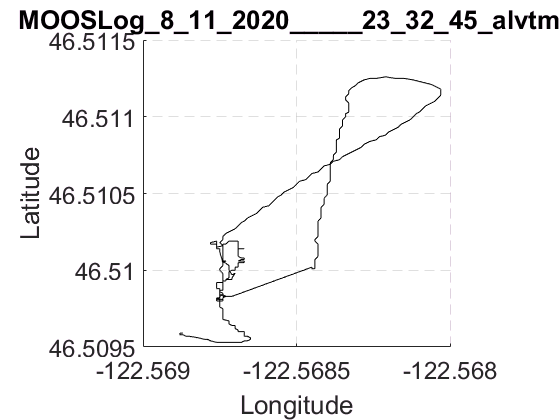

set(gca,'GridLineStyle','--','FontSize',18)
pbaspect([1 1 1])
box off

legend boxoff    
clearvars NAV_latlong

Testing some fancy color stuff

% % figure
% % x = NAV_latlong(:,3);
% % y = NAV_latlong(:,2);
% % z = zeros(size(x));
% % c = sin(.1*(GPS_time_ref-GPS_time_ref(1)));
% % surface([x x],[y y],[z z],[c c],'facecol','no','edgecol','interp','linew',2)
% % pbaspect([1 1 1])